clc
clear

Import

addpath("srcs\all_func\");
imgs = imageDatastore("srcs\imgs", "IncludeSubfolders", false);
img = readimage(imgs, 1);

Plot result from filter

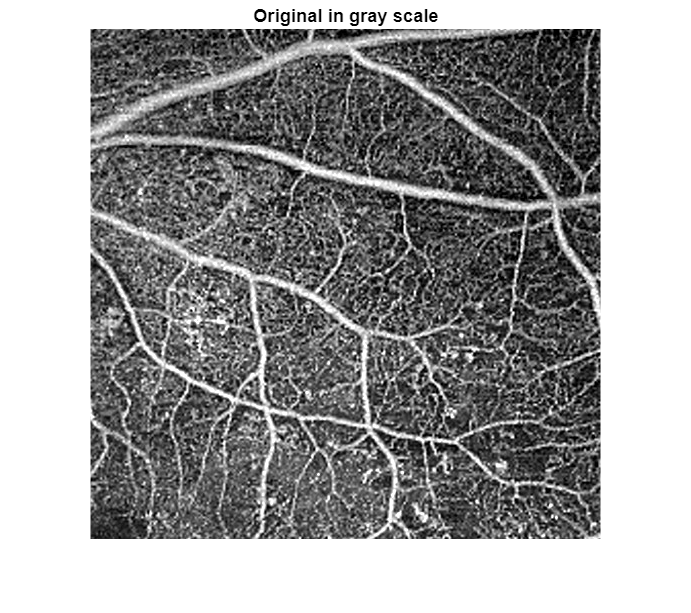

gimg = AllFilters.imagePrepare(img);
med_res = AllFilters.medFilter(img);
gauss_res = AllFilters.gaussFilter(img);
wiener_res = AllFilters.wienerFilter(img);
bilat_res = AllFilters.bilateralFilter(img);
subplot(1, 1, 1);
imshow(gimg);
title("Original in gray scale");

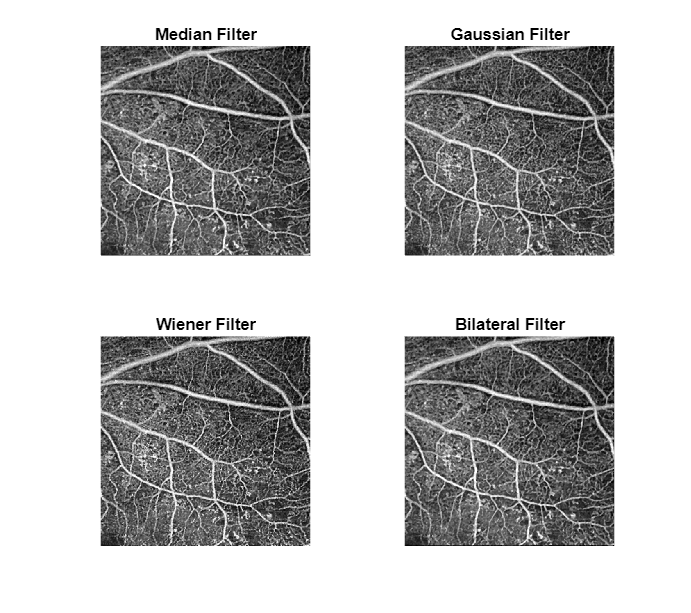


subplot(2, 2, 1);
imshow(med_res);
title("Median Filter");

subplot(2, 2, 2);
imshow(gauss_res);
title("Gaussian Filter");

subplot(2, 2, 3);
imshow(wiener_res);
title("Wiener Filter");

subplot(2, 2, 4);
imshow(med_res);
title("Bilateral Filter");

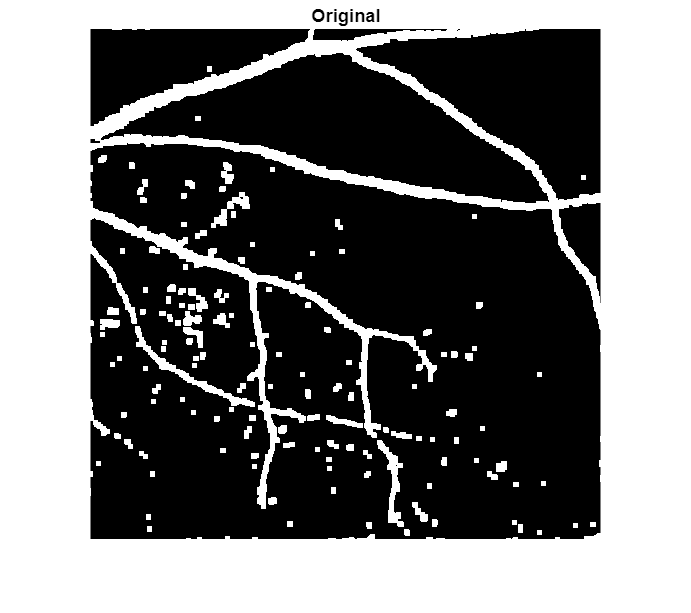

gimg = AllFilters.imagePrepare(img);
morph_org = AllFilters.imClose(img);
f = @AllFilters.imClose;
morph_med_res = f(AllFilters.medFilter(img));
morph_gauss_res = f(AllFilters.gaussFilter(img));
morph_wiener_res = f(AllFilters.wienerFilter(img));
morph_bilat_res = f(AllFilters.bilateralFilter(img));
subplot(1, 1, 1);
imshow(morph_org);

title("Original");

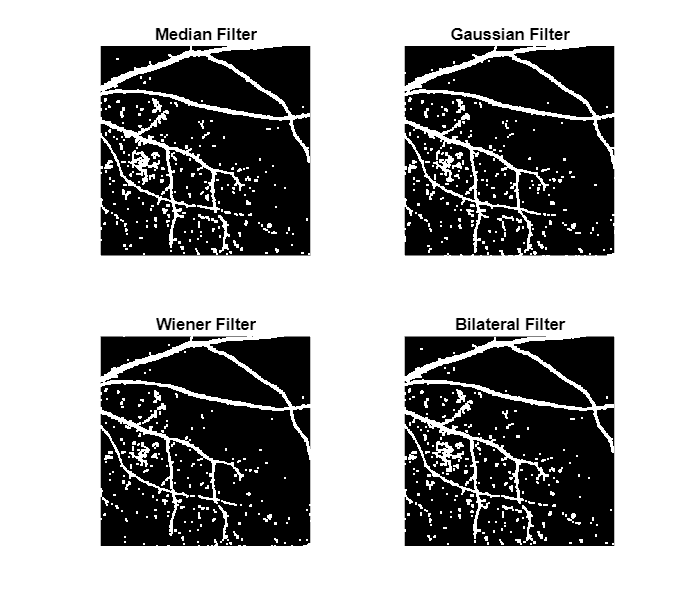

subplot(2, 2, 1);
imshow(morph_med_res);
title("Median Filter");

subplot(2, 2, 2);
imshow(morph_gauss_res);
title("Gaussian Filter");

subplot(2, 2, 3);
imshow(morph_wiener_res);
title("Wiener Filter");

subplot(2, 2, 4);
imshow(morph_med_res);
title("Bilateral Filter");